# DSP Project 

# NB-IoT Base Station Software Defined Radio (SDR) 


clc; 
clear; 
close all;
% Number of NB-IoT devices
optimalfilter=cell2mat(struct2cell(load('3_Equiripple.mat')));
numDevices = 6;
IF_frequency_spacing = 200e3 ;  % Frequency spacing between NB-IoT carriers in Hz
IF_center_frequency = 0;  % Start at 0 Hz  % Center frequency for the composite IF signal in Hz
IF_carrier_freqs = IF_center_frequency + (0:numDevices-1) * IF_frequency_spacing;
% Display the calculated IF frequencies
disp('Calculated IF Frequencies for 6 NB-IoT Devices:')

Calculated IF Frequencies for 6 NB-IoT Devices:


disp(IF_carrier_freqs)

           0      200000      400000      600000      800000     1000000



% Cell array to store waveform and sampling rate for each device
waveforms = cell(1, numDevices);
samplingRates = cell(1, numDevices);

## intializing  the filter coefficients : 

optimalfilter=cell2mat(struct2cell(load('3_Equiripple.mat')));

## Generating the 6 waveforms :

% Loop through each device and generate waveform
for deviceIdx = 1:numDevices
    % Call the generate_NBiot_UL function
    [waveform, Fs] = Generate_NBiot();

    % Store waveform and sampling rate in cell arrays
    waveforms{deviceIdx} = waveform;
    samplingRates{deviceIdx} = Fs; 
end

## **Display information about the generated waveform for one of the devices**


% Display information about the generated waveform for each device
disp(['Generated NB-IoT Uplink Waveform Information for Device ' num2str(deviceIdx) ':']);

Generated NB-IoT Uplink Waveform Information for Device 6:


disp(['Sampling Rate (Fs): ' num2str(Fs) ' Hz']);

Sampling Rate (Fs): 1920000 Hz


disp(['Waveform Length: ' num2str(length(waveform)) ' samples']);

Waveform Length: 153600 samples


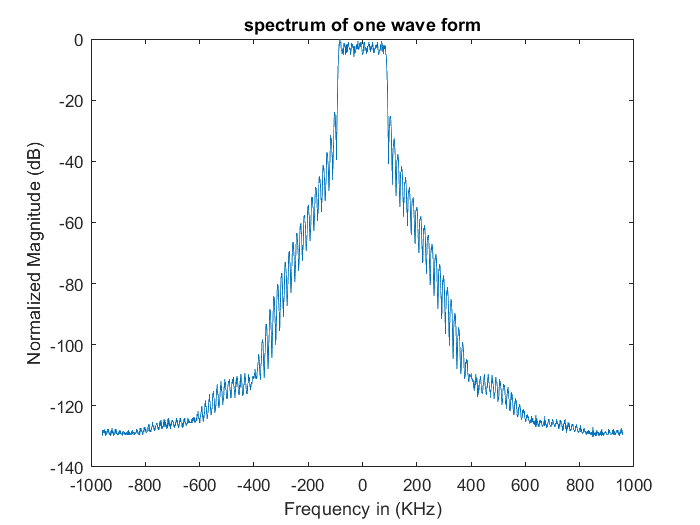

[signal,f] = pwelch(waveform,2048,1024,2048,Fs,"centered");
signal = signal/max(abs(signal));
plot(f/1e3,20*log10((signal)))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')
title ('spectrum of one wave form')

## Creating the composite IF signal

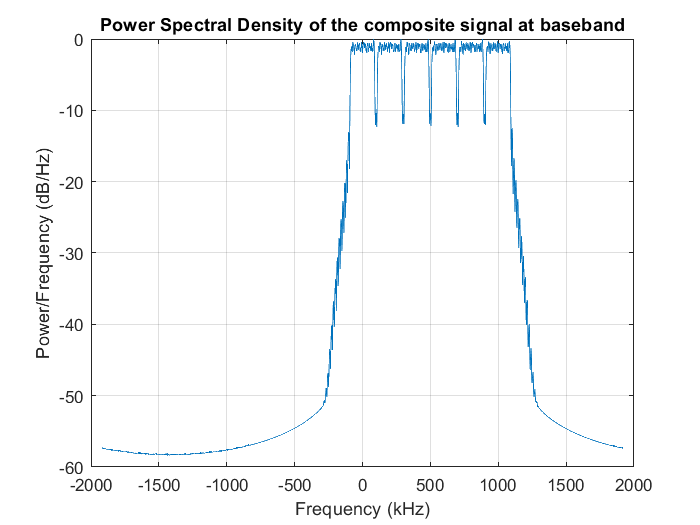

% Create the composite IF signal
composite_IF_signal_upsampled = zeros(1,2*length(waveforms{1}));  % Initialize with the size of one waveform
IF_sampling_rate = 2 * max(IF_center_frequency + (numDevices - 1) * IF_frequency_spacing, Fs);
upsampling_factor = IF_sampling_rate/Fs;
upsampled_signal=zeros(1,2*length(waveforms{1}));
for i = 1:numDevices 
        upsampled_signal = upsample((waveforms{i})', upsampling_factor);
         % Apply low-pass filter
%         lpf = lowpass('Fp,Fst,Ap,Ast', cutoff_frequency, cutoff_frequency * 1.5, 0.1, 80, Fs * upsampling_factor);
        cutoff_frequency = IF_frequency_spacing / (2 * upsampling_factor);
        
        filtered_signal= lowpass(upsampled_signal,cutoff_frequency,IF_sampling_rate);
%         filtered_signal = filter(lpf, 1, upsampled_signal);
        
        % Calculate the carrier frequency for the current device
%         carrier_frequency = IF_center_frequency + (deviceIndex - 1) * IF_frequency_spacing;
        
        % Perform digital upconversion by multiplying with a complex exponential
        t = (0:length(filtered_signal)-1)/ Fs / upsampling_factor  ;
        upconverted_signal = filtered_signal .* exp(1i*2 * pi * IF_carrier_freqs(i) * t);
        
        % Add the upconverted signal to the composite IF signal
        composite_IF_signal_upsampled = composite_IF_signal_upsampled + upconverted_signal;
end
% Plot the magnitude spectrum of the composite IF signal
[IF_signal_spectrum, IF_frequencies] = pwelch(composite_IF_signal_upsampled, 2048, 1024, 2048, Fs * upsampling_factor,"centered");
IF_signal_spectrum = IF_signal_spectrum / max(abs(IF_signal_spectrum));
% Plot the magnitude spectrum
figure;
plot(IF_frequencies/1e3, 10*log10((IF_signal_spectrum)));  % Using log scale for better visualization
xlabel('Frequency (kHz)')
ylabel('Power/Frequency (dB/Hz)')
title('Power Spectral Density of the composite signal at baseband')
grid on;

## using the made function for filter designing : 

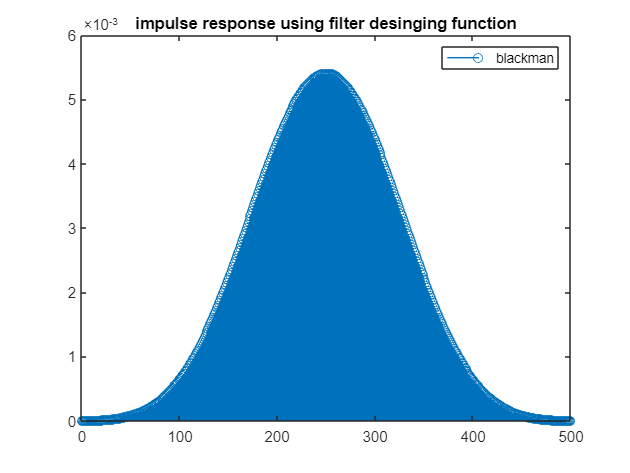

filterIR=design_filter(Fs*2,120000,500,'chebyshev');
% Plot the filtered response

stem(filterIR, 'DisplayName','blackman');
title('impulse response using filter desinging function');
legend('show');

##  calcaulating the most efficient downsampling factor :

downsampling_factor_max=round (Fs*upsampling_factor / 200000)

downsampling_factor_max = 19

downsampling_factor=10;

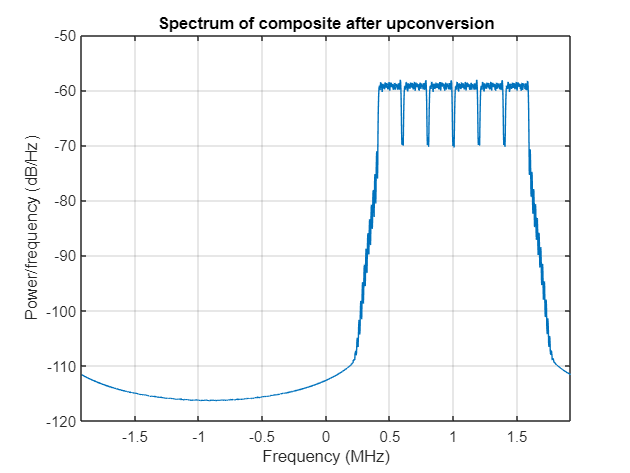

IF_freq = 500e3;
composite_IF_signal_upsampled=composite_IF_signal_upsampled.*exp(1i*2 * pi * IF_freq * t);
pwelch(composite_IF_signal_upsampled, 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum of composite after upconversion');

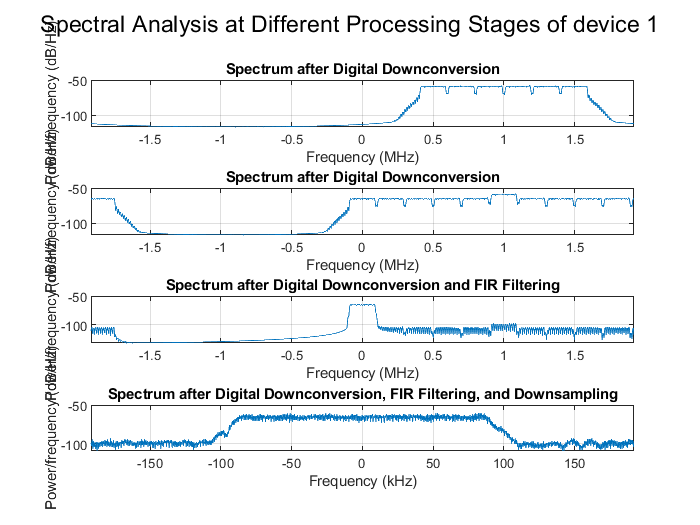

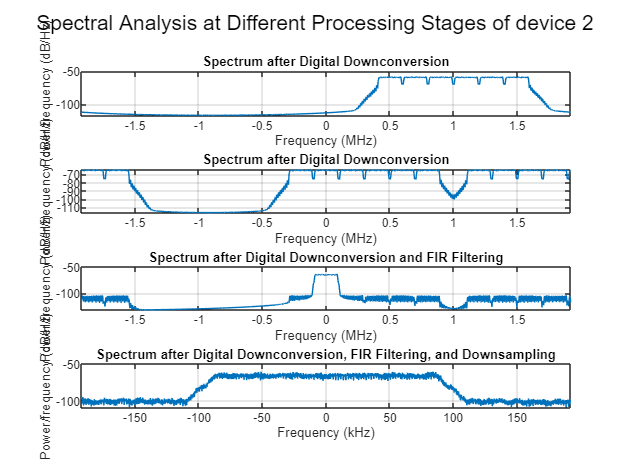

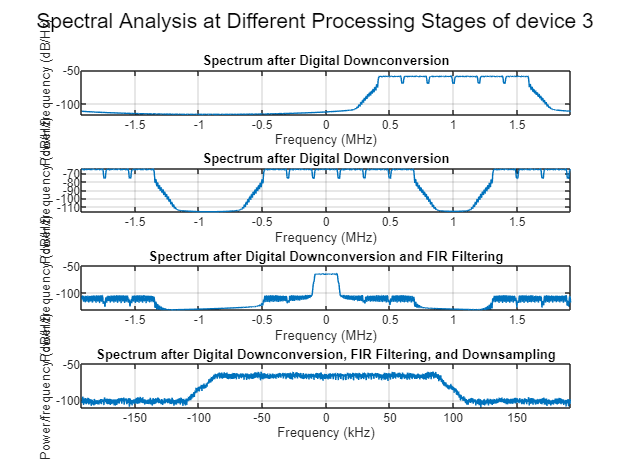

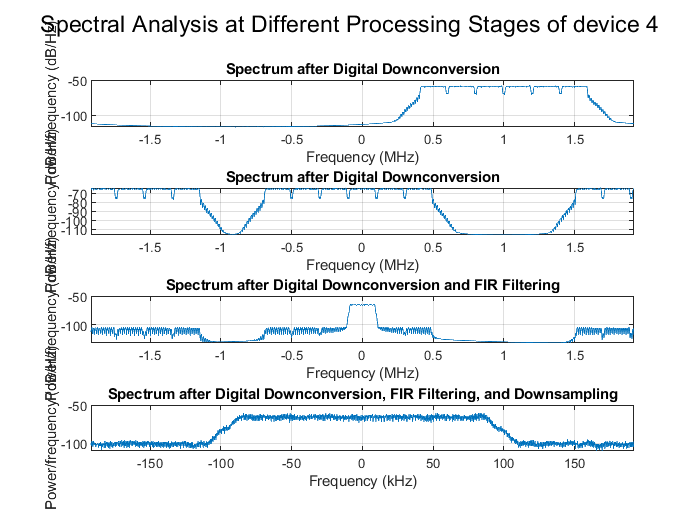

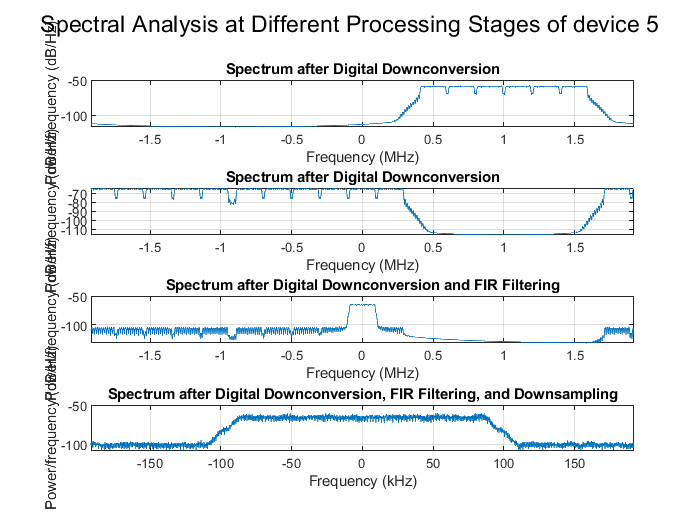

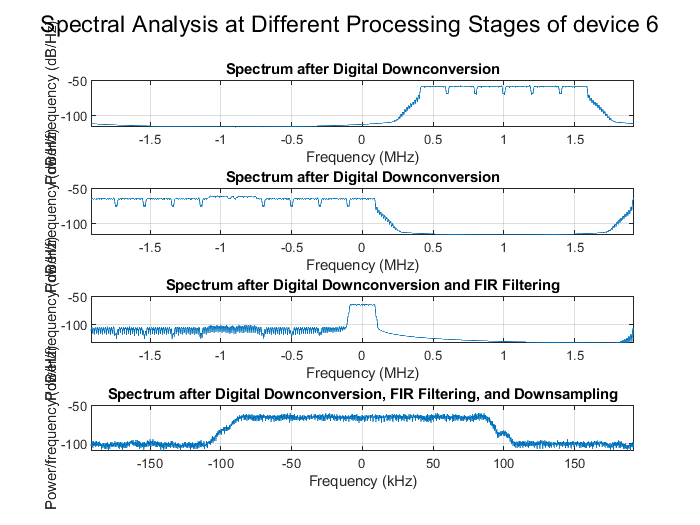


%receiver 
received_waveforms_down_converged = zeros(6,length(composite_IF_signal_upsampled));
received_downsampled = zeros(6,length(waveform')/(downsampling_factor/2));
received_downsampled2 = zeros(6,length(waveform')/(downsampling_factor/2));

receivedfiltered_signal=zeros(6,length(composite_IF_signal_upsampled'));
receivedfiltered_signal2=zeros(6,length(composite_IF_signal_upsampled'));

rx_signal_spectrum= zeros(6,length(signal));
f2=zeros(6,2048);
for i=1:6
    received_waveforms_down_converged(i,:)=composite_IF_signal_upsampled.* cos(2 * pi *(IF_freq + IF_carrier_freqs(i)) * t);
    receivedfiltered_signal(i,:) = filter(optimalfilter',1,received_waveforms_down_converged(i,:));
    receivedfiltered_signal2(i,:) = filter(filterIR',1,received_waveforms_down_converged(i,:));

     
    received_downsampled(i,:) = downsample(receivedfiltered_signal(i,:), downsampling_factor);
    received_downsampled2(i,:) = downsample(receivedfiltered_signal2(i,:), downsampling_factor);

end
for n =1 : 6
figure;
subplot(4,1, 1);
pwelch(composite_IF_signal_upsampled, 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion');
subplot(4,1, 2);
pwelch(received_waveforms_down_converged(n,:), 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion');
subplot(4, 1, 3);
pwelch(receivedfiltered_signal(n,:), 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion and FIR Filtering');
subplot(4, 1, 4);
pwelch(received_downsampled(n,:), 2048, 1024, 2048, IF_sampling_rate/downsampling_factor, 'centered');
title('Spectrum after Digital Downconversion, FIR Filtering, and Downsampling');

sgtitle(['Spectral Analysis at Different Processing Stages of device ',int2str(n)]);

end

Plotting the output using made filter designing function : 

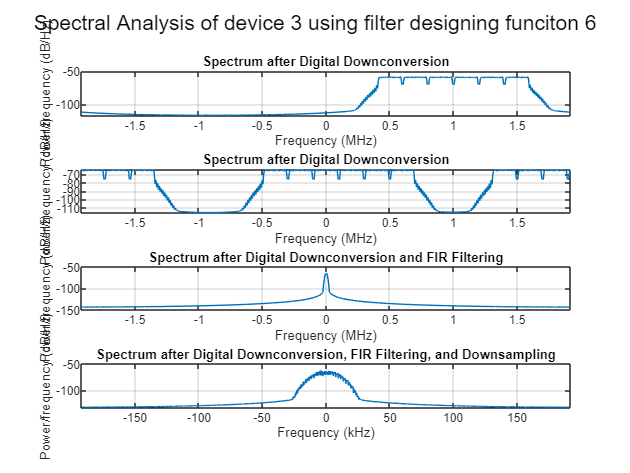

figure;
subplot(4,1, 1);
pwelch(composite_IF_signal_upsampled, 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion');
subplot(4,1, 2);
pwelch(received_waveforms_down_converged(3,:), 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion');
subplot(4, 1, 3);
pwelch(receivedfiltered_signal2(3,:), 2048, 1024, 2048, IF_sampling_rate, 'centered');
title('Spectrum after Digital Downconversion and FIR Filtering');
subplot(4, 1, 4);
pwelch(received_downsampled2(3,:), 2048, 1024, 2048, IF_sampling_rate/downsampling_factor, 'centered');
title('Spectrum after Digital Downconversion, FIR Filtering, and Downsampling');

sgtitle(['Spectral Analysis of device 3 using filter designing funciton ',int2str(n)]);